# **Introductory script illustrating aspects of the TreeShrew cone mosaic**

*This script illustrates how to create the default and customized TreeShrew cone mosaics.*

*Copyright: Nicolas P. Cottaris,  ISETBio Team, 2018*

# **Step 1.** Create and visualize the default TreeShrew cone mosaic

% Start by generating the default tree shew optics. 
% We need to do this because we need to obtain the microns/deg 
% conversion factor for the treeshrew retina, which depends on 
% the focal length of the treeshrew eye.
tOptics = opticsTreeShrewCreate();
umPerDegOnTreeShrewRetina = tOptics.micronsPerDegree;

% Generate the default cone mosaic
tDefaultMosaic = coneMosaicTreeShrewCreate(umPerDegOnTreeShrewRetina);


Resampling grid. Please wait ... Done !
Will not change the S-cone density.
Scones before making an S-cone free central patch: 224
Scones after making an S-cone free central patch: 224 (added Lcones:0, added Mcones:0)
Scones after pass 1: 130 (added Lcones:119, added Mcones:0)
Scones after pass 2: 77 (added Lcones:67, added Mcones:0)
Scones after pass 3: 50 (added Lcones:39, added Mcones:0)
Scones after pass 4: 40 (added Lcones:11, added Mcones:0)
Scones after pass 5: 39 (added Lcones:1, added Mcones:0)
Scones after pass 6: 39 (added Lcones:0, added Mcones:0)


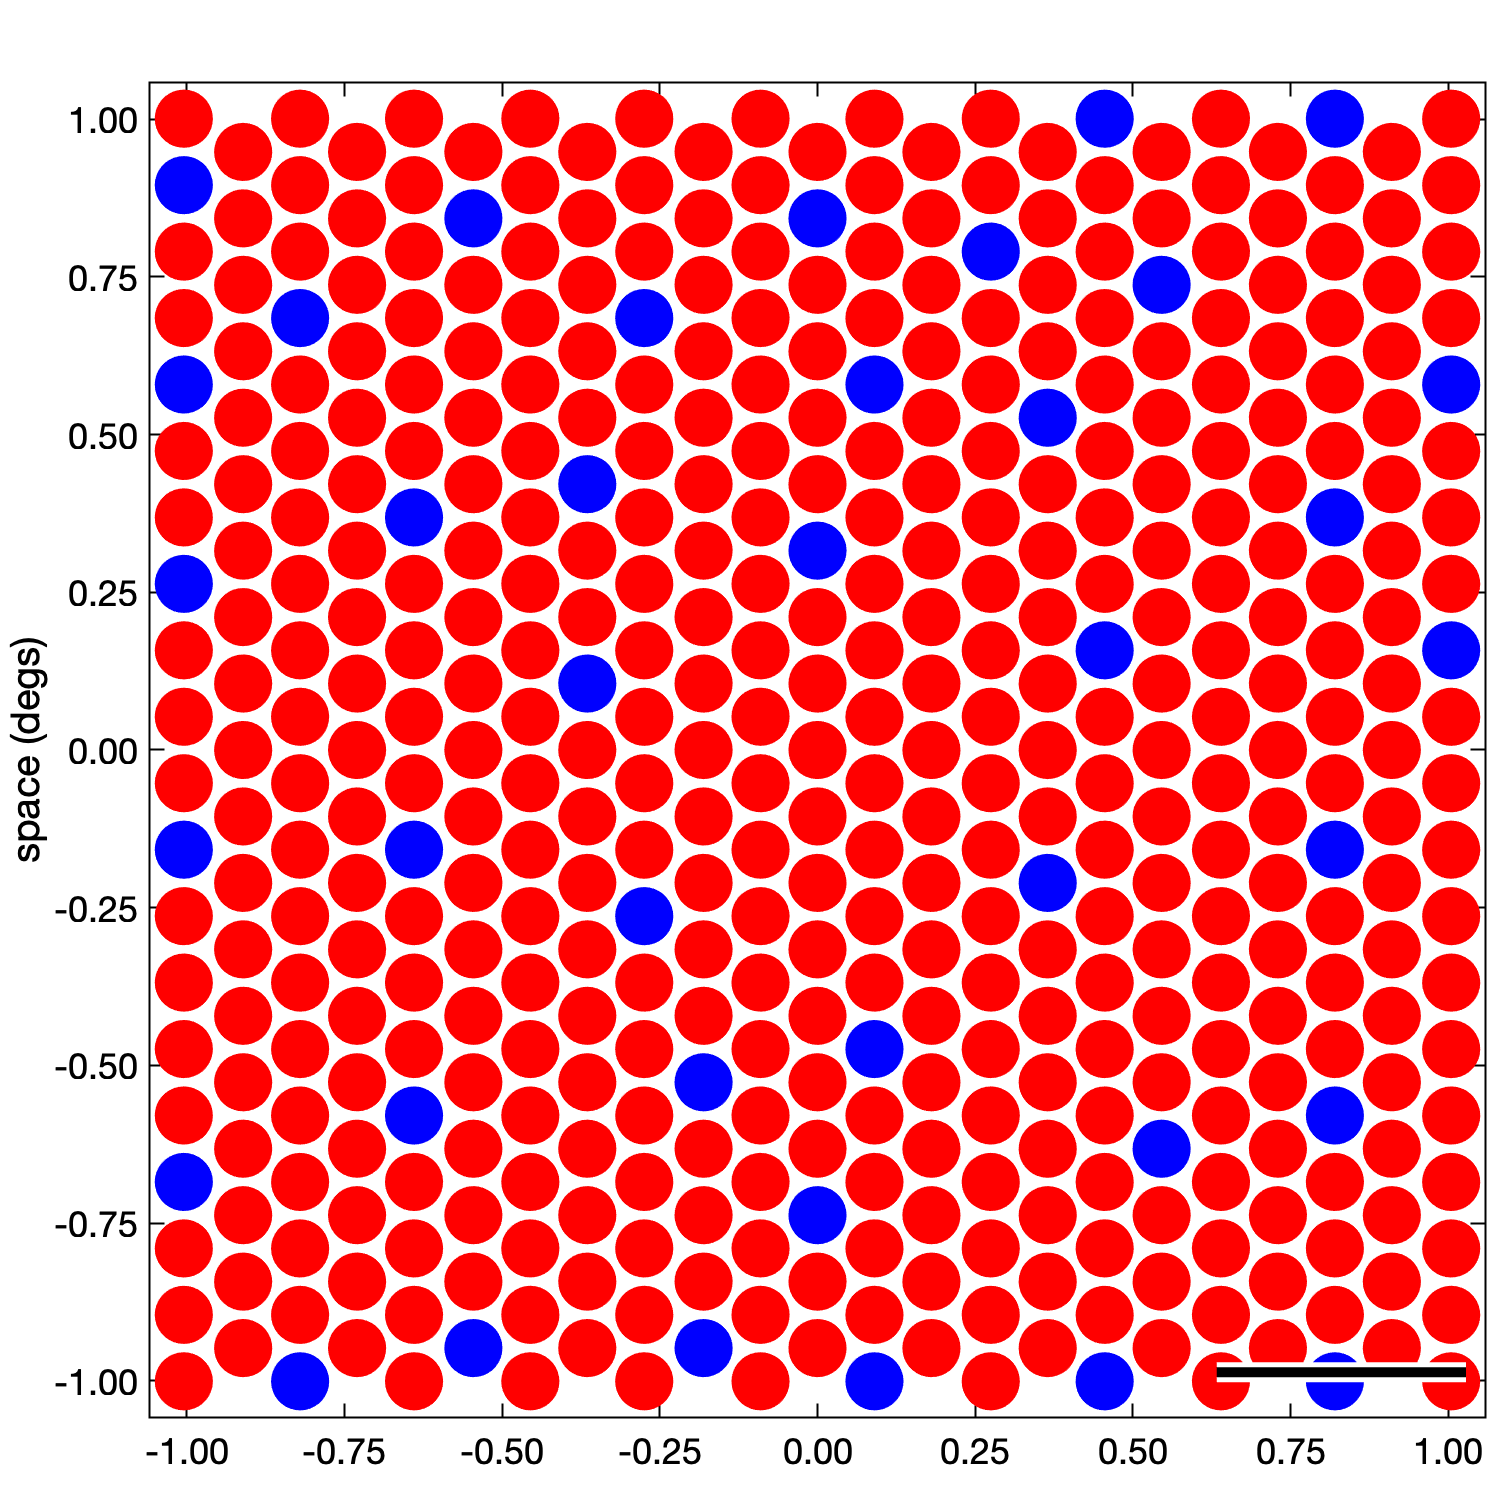


% Visualize the mosaic along with a 30-micron scale bar
tDefaultMosaic.visualizeGrid(...
    'backgroundColor', [1 1 1], ...
    'generateNewFigure', true, ...
    'scaleBarLengthMicrons', 30, ...
    'displayVisualDegs', true);


% Display some info on the mosaic
tDefaultMosaic.displayInfo()


Mosaic info:
                                      Size (microns): 158.0 (w) x 158.0 (h)
                                           FOV (deg): 2.08 (w) x 2.08 (h)
                                   Retinal coverages: 0.681 (aperture) x 0.889 (geometric)
                              Grid resampling factor: 7
                   Inner segment diameter (microns):  Min=1.5797, Mean=2.9404, Median=3.0166, Max=3.8343 
                     Inner segment area (microns^2):  Min=1.9600, Mean=6.7905, Median=7.1468, Max=11.5468 
                     Cone geometric area (microns^2): 50.2655 
               Cone light colleting area (microns^2): 38.4845
                                    Rectangular grid: 20 cols x 20 rows
                                      Resampled grid: 553 cols x 553 rows
                                         Total cones: 305809
                                        Active cones: 449
                                            L- cones: 410 (0.913%)
                   

For comparison, the following figure depicts an S-cone stained whole-mount retina of the TreeShrew (*Figure 3 from Muller et al (1989) "Opsin and S-antigen-like immunoreactions in photoreceptors of the Tree Shrew retina"*). The scale bar is 30 microns, like in the ISETBio figure above.

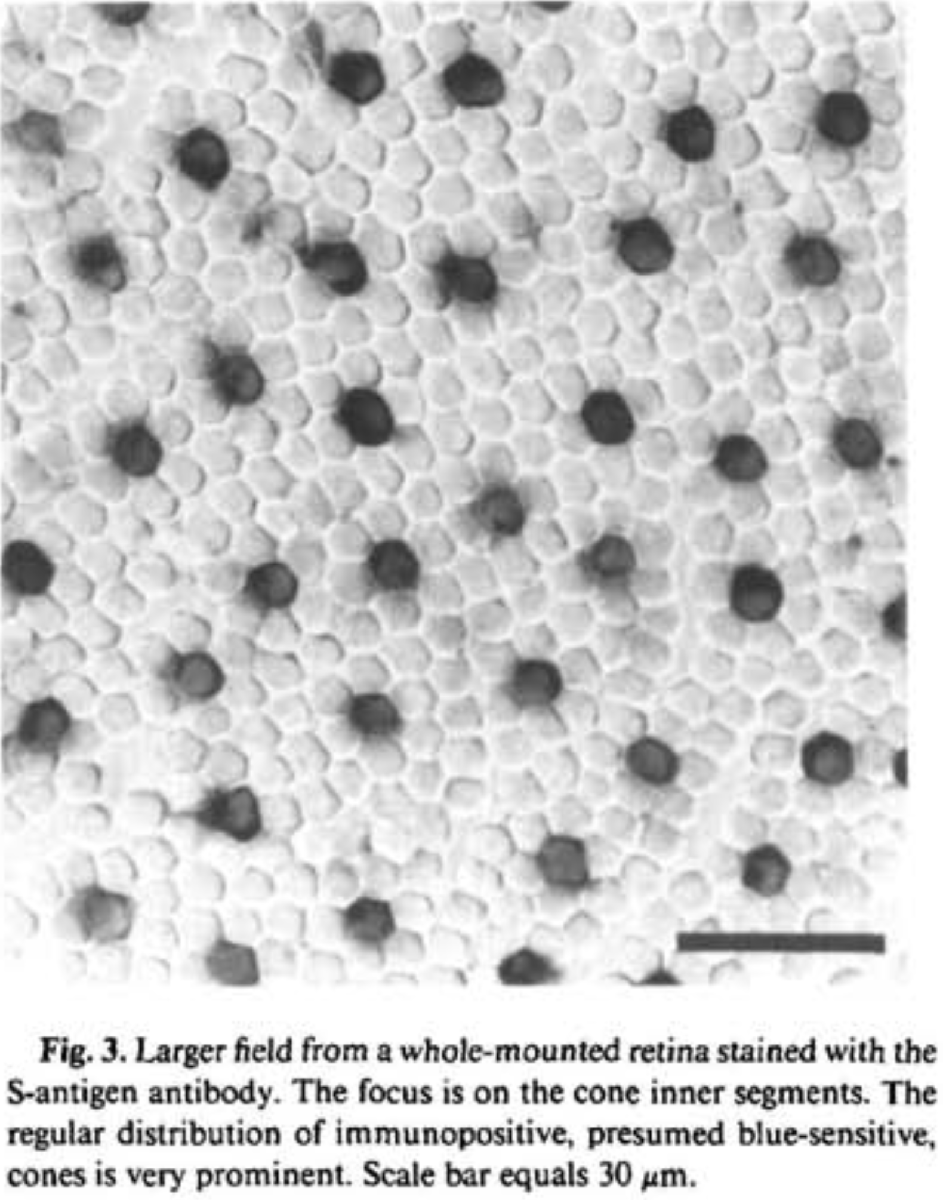

# **Step 2.** Create and visualize a custom TreeShrew cone mosaic

% Generate a custom mosaic with:
% - field of view of 4x4 degs
% - L-and S-cones ratio: 60/40
% - separation between neighboring cones: 10 microns
% - cone inner segment diameter: 6 microns
% - integration time: 50 mseconds
theConeMosaic = coneMosaicTreeShrewCreate(...
    umPerDegOnTreeShrewRetina, ...
    'lConeDensity', 0.6,...
    'sConeMinDistanceFactor', [], ...
    'customLambda', 10, ...
    'customInnerSegmentDiameter', 6, ...
    'fovDegs', [4.0 4.0], ...
    'integrationTime', 50/1000);


Resampling grid. Please wait ... Done !
Will not change the S-cone density.
Scones before making an S-cone free central patch: 427
Scones after making an S-cone free central patch: 427 (added Lcones:0, added Mcones:0)
Will not adjust the minimum S-cone separation
.

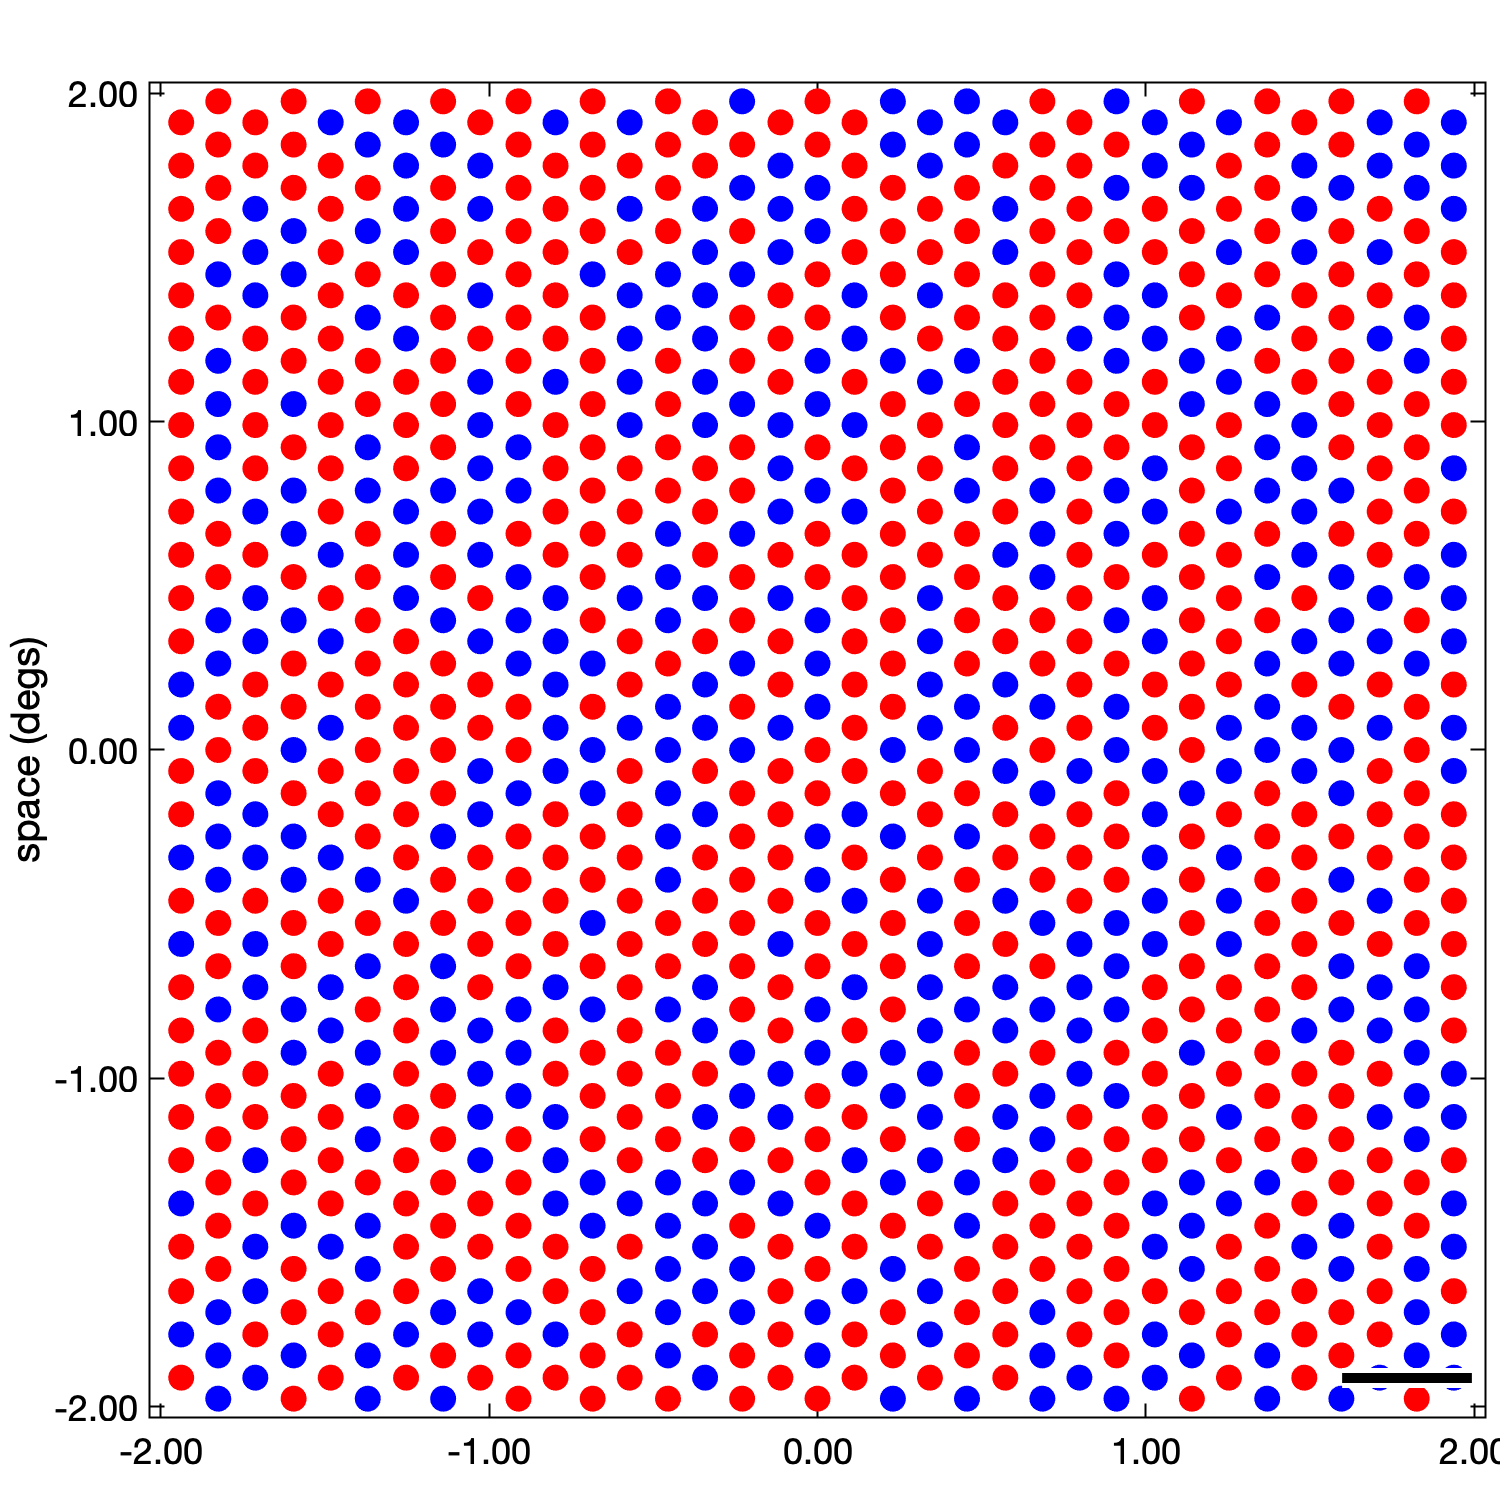


% Visualize the mosaic along with a 30-micron scale bar
theConeMosaic.visualizeGrid(...
    'backgroundColor', [1 1 1], ...
    'generateNewFigure', true, ...
    'scaleBarLengthMicrons', 30, ...
    'displayVisualDegs', true);


% Display some info
theConeMosaic.displayInfo();


Mosaic info:
                                      Size (microns): 306.0 (w) x 306.0 (h)
                                           FOV (deg): 4.03 (w) x 4.03 (h)
                                   Retinal coverages: 0.322 (aperture) x 0.895 (geometric)
                              Grid resampling factor: 7
                   Inner segment diameter (microns):  Min=1.5797, Mean=4.1623, Median=4.3018, Max=5.4540 
                     Inner segment area (microns^2):  Min=1.9600, Mean=13.6068, Median=14.5339, Max=23.3626 
                     Cone geometric area (microns^2): 78.5398 
               Cone light colleting area (microns^2): 28.2743
                                    Rectangular grid: 39 cols x 39 rows
                                      Resampled grid: 1071 cols x 1071 rows
                                         Total cones: 1147041
                                        Active cones: 1067
                                            L- cones: 640 (0.600%)
             